## Initialize the FMCW Radar Computations

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
file_path = "20MHz_USRP.json";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
% file_path = "4GHz.json";
simulator.load_params_from_JSON(david_path + file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 199.86 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 2027.17 m/s
	 Velocity Resolution 		 31.67 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


### Initialize the target

simulator.load_target_realistic(100,-5);

### Initialize the Victim and Simulation Parameters

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

### Initialize the Attacker

%initialize the attacker
%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(0,simulator.Victim,1);
%set to change 1 to zero to disable

%specify the type of emulation ("target", 
        % "velocity spoof - noisy", 
        % "velocity spoof - similar velocity",
        % "range spoof - similar slope")

attack_type = "velocity spoof - similar velocity";
%attack_type = "velocity spoof - similar velocity,range spoof - similar slope ";
%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_type);

%if it is desired to specify a specific attack location
% simulator.Attacker.Subsystem_attacking.set_desired_attack_location(75,7);

## Save the victim chirp to a file

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_chirp_full.bin";
simulator.save_to_file(simulator.Victim.chirp,path);

### Plot Tx Chirp to confirm correctness

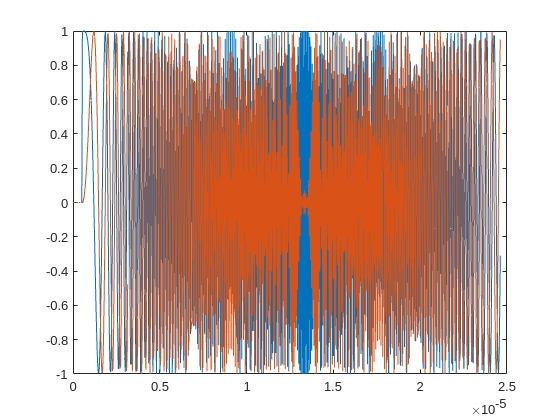

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
data = simulator.Victim.chirp;
plot(t,real(data),t,imag(data))

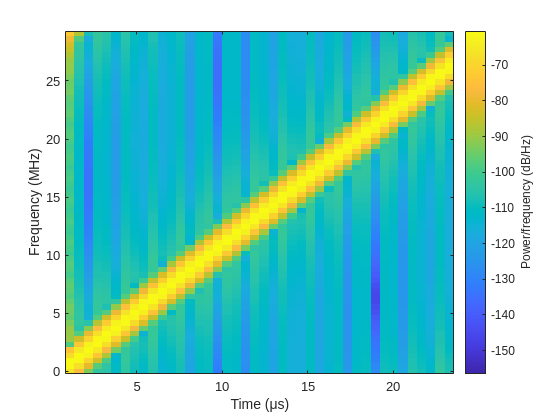

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## RUN EXPERIMENT ON USRP DEVICE

## [Optional] Get sensing system received signal from USRP device

### Read the data recorded by the offline simulation (and optionally plot to confirm correctness

path = "/home/david/Documents/MATLAB_generated/cpp_sensing_stream.bin";
read_data = simulator.read_from_file(path,true);

Not enough input arguments.

Error in Simulator_revB/read_from_file (line 642)
            read_data = fread(fileID,dtype);

samples_to_preview = 1e7;

%generate a spectrogram preview of the sampled signal if desired
clf;
spectrogram(read_data(1:samples_to_preview),64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.FMCW_sampling_period_s * (samples_to_preview -1);
plot(t,real(read_data(1:samples_to_preview)),t,imag(read_data(1:samples_to_preview)))

%re-arrange for processing by the sensing subsystem
spb = 2040;
read_data = reshape(read_data,spb,[]).';

### Run a simulation of the sensing subsystem using USRP data instead of simulated data

simulator.run_sensing_subsystem_with_USRP_data(read_data,true);

### Print out the estimated chirp characteristics:

% %print out the relevant information
fprintf("Number of Frames Detected: %d",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames);
fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);
fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);
fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);

### Save the most recently computed attack chirps to a file so that the attack configuration can use them

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_attacking_chirps_full.bin";

%get the eumulated chirps
write_data = simulator.Attacker.Subsystem_attacking.emulated_chirps;

%reshape to be able to send to a file
write_data = reshape(write_data,[],1);
simulator.save_to_file(write_data,path);

## RUN ATTACK ON MATLAB

### Read Rx data from MATLAB

path = "/home/david/Documents/MATLAB_generated/cpp_rx_data.bin";
read_data = simulator.read_from_file(path,true,"float");

num_chirps = simulator.Victim.NumChirps;
samples_per_chirp = simulator.Victim.ChirpCycleTime_us * 1e-6 * simulator.Victim.FMCW_sampling_rate_Hz;
read_data = reshape(read_data,int32(samples_per_chirp),num_chirps,[]);

%determine the number of frames recorded
num_frames = size(read_data,3);

### Plot Rx Chirp to confirm correctness

Specify chirp:

chirp =1;

Specify frame:

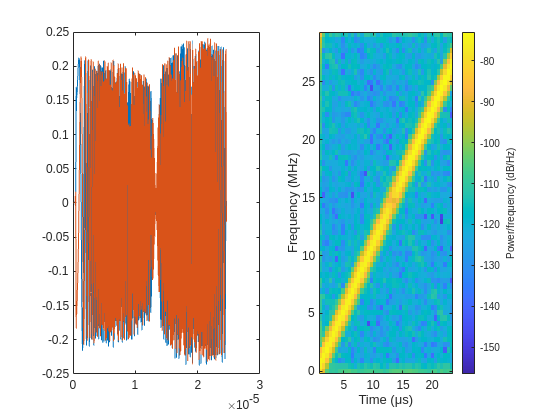

frame = 5;
% the chirp signal
%chirp = 251;
%frame = 20;
first_frame = read_data(:,:,1);
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
clf;
subplot(1,2,1);
plot(t,real(read_data(:,chirp,frame)),t,imag(read_data(:,chirp,frame)))
subplot(1,2,2)
spectrogram(read_data(:,chirp,frame),64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

### Process received Rx Signal

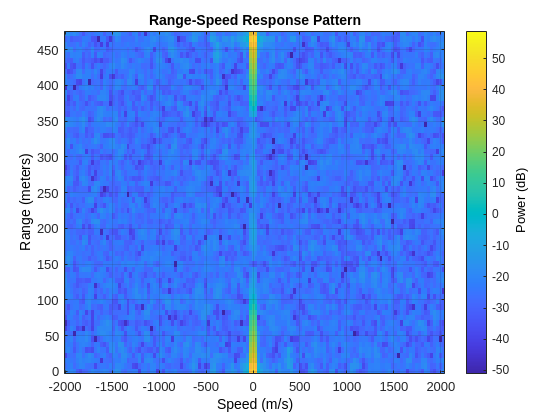

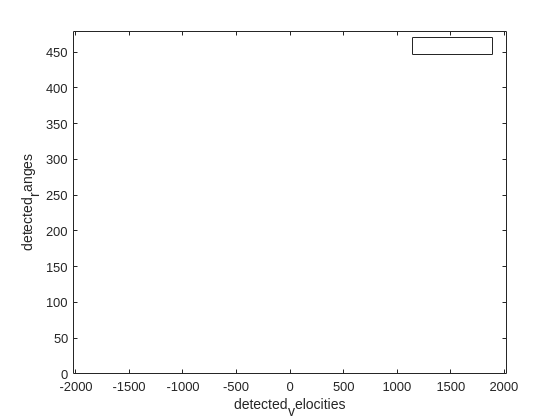

%specify the number of frames and chirps to compute
clf;
frames_to_compute = size(read_data,3);
chirps_to_compute = simulator.Victim.NumChirps;

%get the radar chirp generator and the target emulator ready
simulator.Victim.precompute_radar_chirps();


F_rngdop(frames_to_compute) = struct('cdata',[],'colormap',[]);
F_clusters(frames_to_compute) = struct('cdata',[],'colormap',[]);

for frame = int32(1:frames_to_compute)
    
    %initialize a clean radar cube
    radar_cube = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps);
    
    for chirp = int32(1:chirps_to_compute)
    
        %get the Tx chirp and the chirp received from the emulator
        Rx_sig = read_data(:,chirp,frame);
        Tx_sig = simulator.Victim.chirps(:,chirp);      
        
        %dechirp and downsample the signal
        sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.FMCW_dechirp_and_decimate(Tx_sig,Rx_sig);
        
        %assemble the radar cube
        radar_cube(:,chirp) = sampled_IF_sig;
    end
    
    %range-doppler response
    [resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);

    %CA CFAR 2-D
    detections = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(...
        abs(resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);
    detected_velocities = dopgrid(detections(2,:));
    detected_ranges = rnggrid(detections(1,:));
    
    
    
    %estimate the range and the velocities
    if ~isempty(detections)
    
        %DBSCAN Clustering
        idx = dbscan(detections.',...
            simulator.Victim.Radar_Signal_Processor.Epsilon,...
            simulator.Victim.Radar_Signal_Processor.minpts);
    
        %plot the range-doppler and clustering responses
        
        %plot range doppler
        plotResponse( ...
            simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse, ...
            radar_cube);
        drawnow
        F_rngdop(frame) = getframe(gcf);
    
        %plot the clusters
        gscatter(detected_velocities,detected_ranges,idx);
        axis([-1 * ...
            simulator.Victim.Radar_Signal_Processor.Radar.V_Max_m_per_s, ...
            simulator.Victim.Radar_Signal_Processor.Radar.V_Max_m_per_s, ...
            0,simulator.Victim.Radar_Signal_Processor.Radar.Range_Max_m]);
        drawnow
        F_clusters(frame) = getframe(gcf);
    else
        %plot range doppler
        plotResponse( ...
            simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse, ...
            radar_cube);
        drawnow
        F_rngdop(frame) = getframe(gcf);
    
    
        %plot the clusters
        clf;
        detected_velocities = [0];
        detected_ranges = [0];
        idx = [1];
        gscatter(detected_velocities,detected_ranges,idx);
        axis([-1 * ...
            simulator.Victim.Radar_Signal_Processor.Radar.V_Max_m_per_s, ...
            simulator.Victim.Radar_Signal_Processor.Radar.V_Max_m_per_s, ...
            0,simulator.Victim.Radar_Signal_Processor.Radar.Range_Max_m]);
        cla;
        drawnow
        F_clusters(frame) = getframe(gcf);
    end
end

%play the range doppler movie for the output
clf;
fig = figure;
movie(fig,F_rngdop,1,10);

clf;
fig = figure;
movie(fig,F_clusters,1,10);

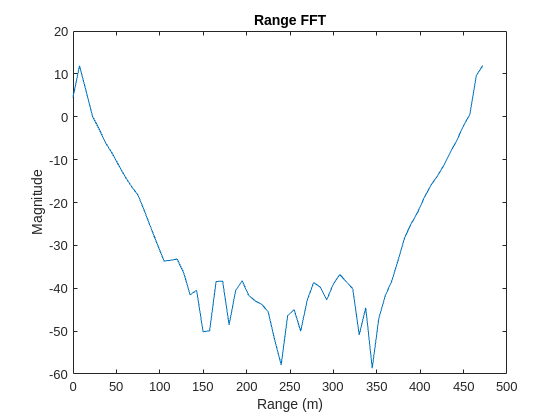

window = hann(simulator.Victim.ADC_Samples);
windowed_sig = window .* radar_cube(:,1);
range_fft = 20 * log10(abs(fft(windowed_sig)));
clf;
plot(simulator.Victim.Ranges,range_fft)
xlabel("Range (m)");
ylabel("Magnitude");
title("Range FFT")

## Code to align the rx and the tx signal using cross correlation

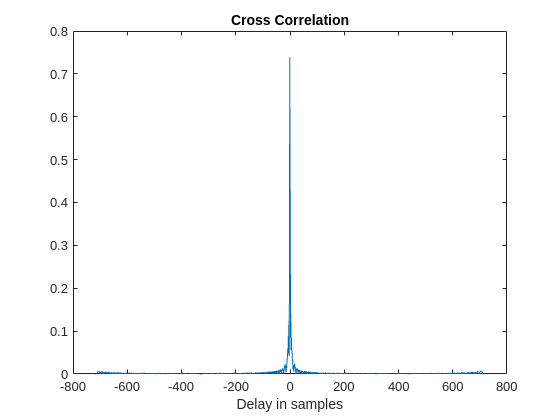

[C,lag] = xcorr(Rx_sig,Tx_sig,"normalized");
clf;
plot(lag,abs(C));
xlabel("Delay in samples")
title("Cross Correlation")

[M,I] = max(abs(C));
delay_samps = lag(I)

delay_samps = -1

delay_us = delay_samps * simulator.Victim.FMCW_sampling_period_s * 1e6

delay_us = -0.0339

% plot(lag,C,[t21 t21],[-0.5 1],'r:')
% text(t21+100,0.5,['Lag: ' int2str(t21)])
% ylabel('C_{21}')